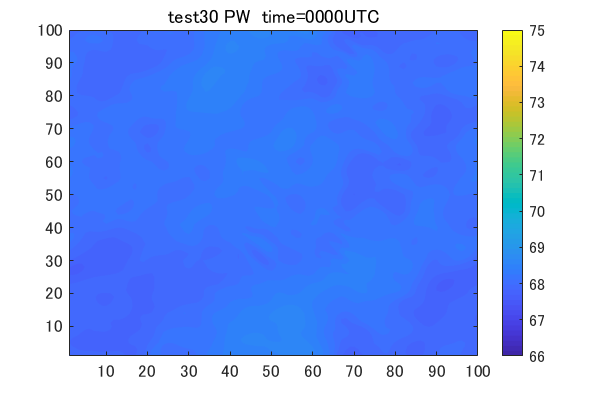

close all
clear
%---setting
expri='test30';  varinam='PW';
year='2018'; mon='09'; date=19;
hr=00:24; minu='00'; 
n=0;
indir='E:/wrfout/expri191009/';
outdir='E:/figures/expri191009/';
filename=[outdir,expri,'_gif_',varinam,'.gif'];
h=figure('Position',[100 100 600 400]);

%---
for ti=hr
  %s_hr=num2str(ti,'%2.2d');
  
  if ti>=48
       s_date=num2str(date+2,'%2.2d');
       s_hr=num2str(ti-48,'%2.2d');
  elseif ti>=24
       s_date=num2str(date+1,'%2.2d');
       s_hr=num2str(ti-24,'%2.2d');
  else
       s_date=num2str(date,'%2.2d');
       s_hr=num2str(ti,'%2.2d');
  end   
     
  infile = [indir,expri,'/wrfout_d01_',year,'-',mon,'-',s_date,'_',s_hr,'%3A',minu,'%3A00'];
  qv = ncread(infile,'QVAPOR');  
  pb = ncread(infile,'PB'); 
  p = ncread(infile,'P');
  % 
  P=(pb+p); dP=P(:,:,1:end-1,:)-P(:,:,2:end,:);
  tpw= dP.*( (qv(:,:,2:end,:)+qv(:,:,1:end-1,:)).*0.5 ) ;
  PW=squeeze(sum(tpw,3)./9.81);
  %---
  t2 = ncread(infile,'T2');  
  
%---
  contourf(PW',20,'linestyle','none')

  title([expri,' ',varinam,'  time=',s_hr,minu,'UTC'],'FontSize',15)
  colorbar;  %caxis([42 60])
  caxis([66 75])
  set(gca,'fontsize',13)
  
  n=n+1;
  frame=getframe(h);  im=frame2im(frame);
  [imind, cm]=rgb2ind(im,256);
  if n == 1 
    imwrite(imind,cm,filename,'gif','Loopcount',Inf,'DelayTime',0.2); 
  else 
    imwrite(imind,cm,filename,'gif','WriteMode','append'); 
  end   

end %time

%close all
clear
%---setting
expri='test15';  varinam='PW';
year='2019'; mon='08'; date=19;
hr=6; minu='00'; 
n=0;

filename=[expri,'_',varinam,'.gif'];

%---
for ti=hr
  %s_hr=num2str(ti,'%2.2d');
  
  if ti>=48
       s_date=num2str(date+2,'%2.2d');
       s_hr=num2str(ti-48,'%2.2d');
  elseif ti>=24
       s_date=num2str(date+1,'%2.2d');
       s_hr=num2str(ti-24,'%2.2d');
  else
       s_date=num2str(date,'%2.2d');
       s_hr=num2str(ti,'%2.2d');
  end   
     
  infile = [expri,'/wrfout_d01_',year,'-',mon,'-',s_date,'_',s_hr,'%3A',minu,'%3A00'];
  qv = ncread(infile,'QVAPOR');  
  pb = ncread(infile,'PB'); 
  p = ncread(infile,'P');
  % 
  P=(pb+p); dP=P(:,:,1:end-1,:)-P(:,:,2:end,:);
  tpw= dP.*( (qv(:,:,2:end,:)+qv(:,:,1:end-1,:)).*0.5 ) ;
  PW=squeeze(sum(tpw,3)./9.81);
  %---
  t2 = ncread(infile,'T2');  
  
%---
  figure('Position',[100 100 600 400]);
  contourf(PW',20,'linestyle','none')

  title([expri,' ',varinam,'  time=',s_hr,minu],'FontSize',15)
  colorbar;  %caxis([298.5  301])
  set(gca,'fontsize',13)
 


end %time






% %zi=3;
% varinam='TPWqv';
% %eval(['variplot=double(permute(',varinam,',[2 1 3]));']);
% eval('variplot=double(permute(TPW,[2 1 3]));');
% filename=[expri,'_gif_',varinam,'.gif'];
% h=figure('Position',[100 100 600 400],'color','w');
% 
% n=0;
% for ti=2:48
%   n=n+1; 
%   %plotvar=variplot(:,:,zi,ti);
%   plotvar=variplot(:,:,ti); %plotvar(plotvar<0.001)=NaN;
%   [~, hp]=contourf(plotvar,20);   set(hp,'linestyle','none');
%   %---plot height
%   %hold on; contour(hgt(:,:,1)',[100 100],'color',[0 0 0],'Linewidth',1);
%   
%   cmap=flipud(parula); %cmap(1,:)=[1 1 1];
%   colormap(cmap)
%   hc=colorbar; set(hc,'fontsize',13)
%   title(hc,'Kg/m^2','FontSize',15)
%   %caxis([0 90])
%   caxis([20 55])
%   
%   set(gca,'fontsize',13,'linewidth',1.5,'Xtick',50:100:400,'Xticklabel',100:200:800 ...
%         ,'ytick',50:100:400,'Yticklabel',100:200:800)
%   xlabel('km','fontsize',13);   ylabel('km','fontsize',13);
%         
%  % title(['Rain wanter level',num2str(zi),', ti=',num2str(ti)],'FontSize',20)
%   title([expri,' PW, ',num2str(ti*15),'min'],'FontSize',20)
% 
%   frame=getframe(h);  im=frame2im(frame);
%   [imind, cm]=rgb2ind(im,256);
%   if n == 1 
%     imwrite(imind,cm,filename,'gif','Loopcount',Inf,'DelayTime',0.2); 
%   else 
%     imwrite(imind,cm,filename,'gif','WriteMode','append'); 
%   end 
% end
% %%


